**ESTIMATION OF FRICTION PARAMETERS**

In this part its is necessary to load the data obtained from the stair input sequence with $\Delta =50\;$rpm. We need to import data both for the positive and negative stair. 

Pay al lot of attention when saving the output!! Use the correct name and *rename OUT*.

Each operation must be repeated both for postive and negative stair sequence

load('positive_stair.mat')
load('negative_stair.mat')

**Butterwoth high-pass filter **(this is useful in all the lab)

filt.wci = 2*pi*20;
filt.di = 1/sqrt(2);
sysHi = tf(filt.wci^2,[1 2*filt.di*filt.wci filt.wci^2]);
sysHi = c2d(sysHi, Ts, 'tustin');
[numHi, denHi] =tfdata(sysHi, 'v');

Current filtering

proc.iaf_positive = filter(numHi, denHi, positive_stair.ia.Data);
proc.iaf_negative = filter(numHi, denHi, negative_stair.ia.Data);

Quantities needed fot the estimation (wrt motor, measured ones are wrt load)   

*CHECK* - ia plot

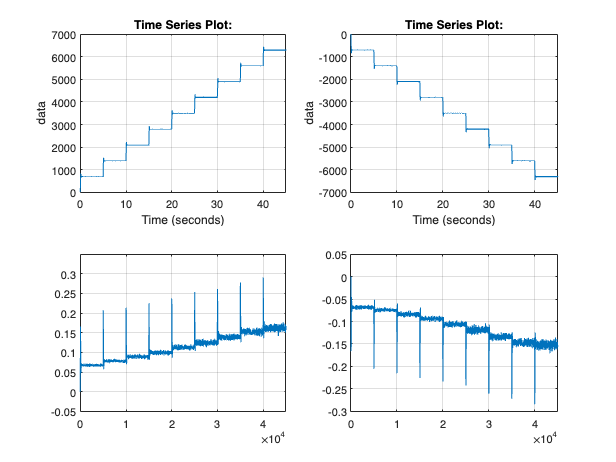

proc.wm_positive = gbox.N*positive_stair.wl_meas;
proc.taum_positive = mot.Kt*proc.iaf_positive;

proc.wm_negative = gbox.N*negative_stair.wl_meas;
proc.taum_negative = mot.Kt*proc.iaf_negative; 

% Figure to check everithing is ok
figure;
subplot(2,2,1);
plot(proc.wm_positive);
grid on;
subplot(2,2,3);
plot(proc.iaf_positive);
grid on;
axis([0 45000 -0.05 0.35])
subplot(2,2,2);
plot(proc.wm_negative);
grid on;
subplot(2,2,4);
plot(proc.iaf_negative);
grid on;

**Least Squares Estimation **

Repeat the estimate both for positive and negative data. Then take the average value.   

TOFIX:     we tested the function with old data. it is not possible to test the mean due to variable step solver

est.phi_positive = zeros(2,9);
est.phi_negative = zeros(2,9);
est.Y_positive = zeros(1, 9);
est.Y_negative = zeros(1, 9);

% Estimation of the average values
for i=1:9
    ind = [5000*(i-1)+200:5000*(i-1)+800];

    est.phi_positive(1,i) = mean(proc.wm_positive(ind));
    est.phi_postive(2,i) = 1/gbox.N*sign(est.phi_postive(1,i));
    est.Y_positive(i) = mean(proc.iaf_positive(ind)); 

    est.phi_negative(1,i) = mean(proc.wm_negative(ind));
    est.phi_negative(2,i) = 1/gbox.N*sign(est.phi_negative(1,i));
    est.Y_negative(i) = mean(proc.iaf_negative(ind));

    
    est.Y(i)=mean(temp2); 
end

Unrecognized function or variable 'wmn'.


est.theta=((est.phi*est.phi.')^-1)*est.phi*est.Y.'

PAY ATTENTION: save est.theta for each simulation

OLD MATERIAL - TO FIX - TRIANGULAR CASE




% filtraggio
ia = filter(numHi, denHi, ia);
plot(t,ia)
grid on

%% Ha low-pass

wca = 2*pi*20;
da = 1/sqrt(2);
sysFa = tf([wca^2 0],[1 2*da*wca wca^2]);
sysFa = c2d(sysFa, Ts, 'tustin');
[numFa, denFa] =tfdata(sysFa, 'v');


% filtraggio
al = filter(numFa, denFa, wm);
am = gbox.N*al;

%% Calcolo delle medie di interesse [a]

amean = zeros(20,1);
for i = 0:19
    amean(i+1) = mean(am(1000*i+200:1000*i+800));
end

%%

taum_k = mot.Kt*ia;

%tau_f = thetaLSopt(1)*3*wm/rpm2rads+thetaLSopt(2)/N*sign(wm)*10;
tau_f = LSopt(1)*wm/rads2rpm + LSopt(2)/gbox.N;

tau_i = taum_k - tau_f;

%%
figure
subplot(2,2,1)
plot(wm*gbox.N)
ylabel('\omega_{m}')
axis([0 8000 0 7000])
grid on

subplot(2,2,2)
plot(am)
ylabel('a_{m}')
axis([0 8000 -12000 12000])
grid on

subplot(2,2,3)
plot(ia)
%hold on
%plot(tau_f/mot.Kt)
ylabel('i_{a}')
axis([0 8000 -0.1 0.25])
grid on

subplot(2,2,4)
plot(tau_i)
ylabel('\tau_{i}')
axis([0 8000 -0.0008 0.0008])
grid on

%%
% 
% wm_plot=[50 100 150 200 250 300 350 400 450]*N;
% figure
% stem(wm_plot,tau_m_k)
% hold on
% plot(wm_plot, theta(1)*wm_plot+1/N*0.01)


